# 2 Motor Step Response Experiment

#### Demo 1 for SEED Lab

Alex Curtis

This script will find transfer functions for both motors using step response data, and find eventually create a controller to make sure the robot moves in a straight line.

This script runs the step response experiment I created in stepResponse.ino, interperets the data, makes some beautiful plots, determines an accurate transfer function for the motor, and tunes a PI controller to desired specifications. 

*Upload the stepResponse code to the Arduino before running.*

#### Clear previous workspace data

clear dataTable dataArray

#### Automatically find the port the Arduino is connected to

allPorts = serialportlist;  % list of all available ports
pat = "/dev/cu.usbmodem";   % text to look for

% logical array of matching ports
matchingPorts = startsWith(allPorts, pat);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard);

#### Tell the Arduino to start the forward velocity experiment (#1)

disp('Starting forward velocity experiment in Arduino')

Starting forward velocity experiment in Arduino


writeline(ard,"1"); % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end

clear ard newData k; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1)-1000)/1000;

% Create a table to store the data
%dataTable = array2table(dataArray,"VariableNames",{'time', 'sum', 'dif', 'fVel', 'rVel'})
dataTable = array2table(dataArray,"VariableNames",{'time', 'motor', 'velR', 'posR', 'velL', 'posL'})

dataTable = 201×6 table
    time     motor     velR       posR       velL       posL   
    _____    _____    ______    ________    ______    _________

        0     400          0           0         0            0
    0.005     400     0.7854           0    0.3927            0
     0.01     400     1.5708    0.003927    1.9635    0.0019635
    0.015     400     3.1416    0.011781    2.7489     0.011781
     0.02     400     3.5343    0.027489    3.5343     0.025525
    0.025     400     4.3197     0.04516    4.3197     0.043197
     0.03     400     5.1051    0.066759    5.4978     0.064795
    0.035     400     4.3197    0.092284    4.7124     0.092284
     0.04     400     6.6759     0.11388    6.6759      0.11585
    0.045     400     7.0686     0.14726    7.0686      0.14923
   

% Save data to a .mat file
save steerData.mat dataTable

#### Plot the data (raw motor response)

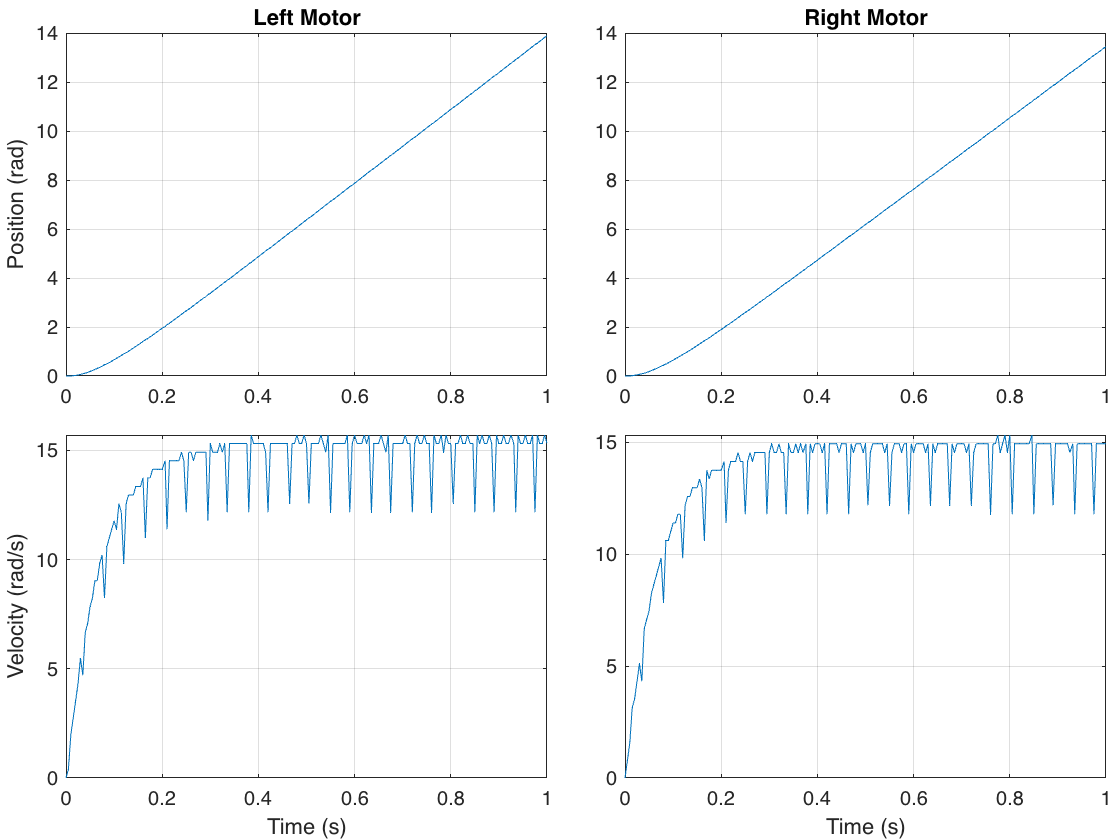

t = tiledlayout(2,2,'TileSpacing','Compact','Padding','tight');

nexttile
plot(dataTable.time,dataTable.posL)
title('Left Motor')
ylabel('Position (rad)')
grid on

nexttile
plot(dataTable.time, dataTable.posR)
title('Right Motor')
grid on

nexttile
plot(dataTable.time,dataTable.velL)
xlabel('Time (s)')
ylabel('Velocity (rad/s)')
grid on

nexttile
plot(dataTable.time,dataTable.velR)
xlabel('Time (s)')
grid on

#### Process data

Smoothing the velocity data gets rid of any noise that might mess up my resulting transfer function.

newT = dataTable;

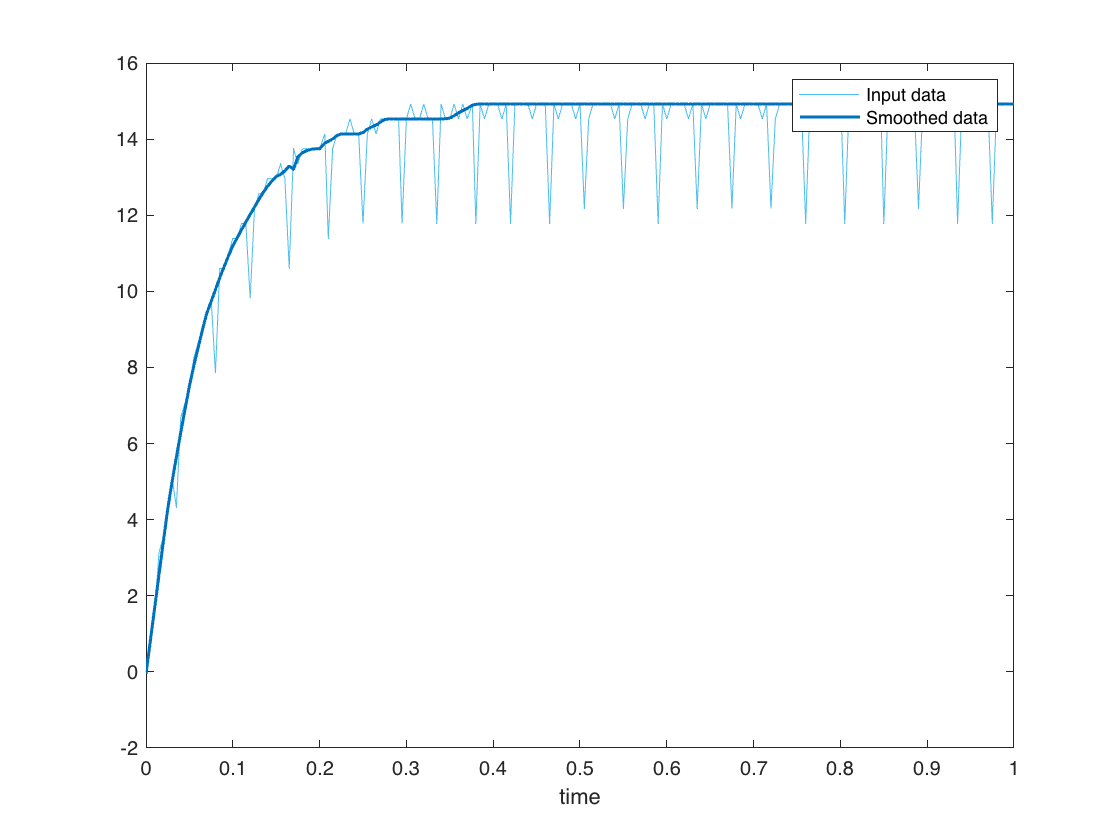

% Smooth input data
smoothedData = smoothdata(dataTable.velR,"rlowess","SmoothingFactor",0.25,...
    "SamplePoints",dataTable.time);

% Display results
clf
plot(dataTable.time,dataTable.velR,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(dataTable.time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")

newT.velR = smoothedData;

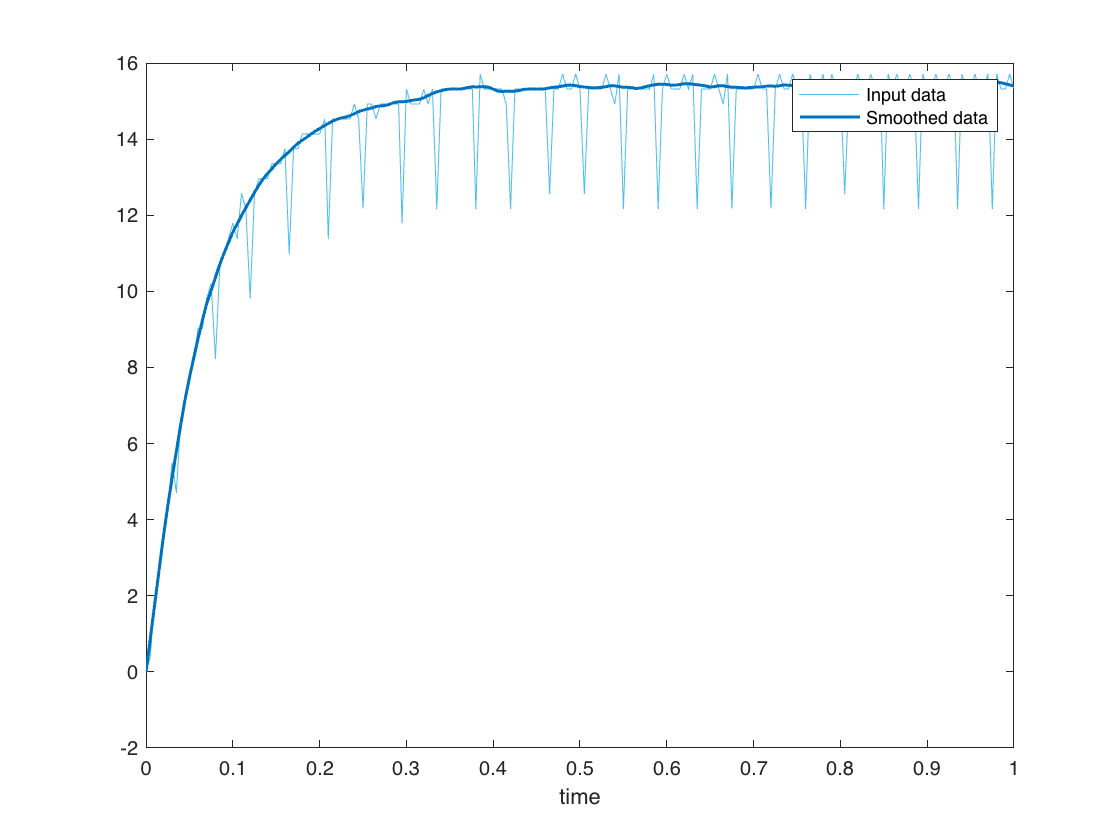

% Smooth input data
smoothedData2 = smoothdata(dataTable.velL,"rlowess","SmoothingFactor",0.25,...
    "SamplePoints",dataTable.time);

% Display results
clf
plot(dataTable.time,dataTable.velL,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(dataTable.time,smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")

newT.velL = smoothedData2;

Max analogWrite command = 255

max motor.setM1Speed() command = 400

Since the motor command is a number out of 400, I need to divide the velocity by 400 to get a unit step response.

**THIS HAS NOTHING TO DO WITH THE VOLTAGE ON THE BATTERY.**

newT.velR = newT.velR/400; newT.velL = newT.velL/400;

#### Determine Transfer Function of Motor Command to Velocity

Find the steady state velocity of the motor (K)

K_R = newT.velR(newT.time > 0.4); KD_L = newT.velL(newT.time > 0.4);
K_R = mean(K_R), KD_L = mean(KD_L)

K_R = 0.0373

K_L = 0.0385

find 0.64 * K and the time constant to find sigma.

magAt64K_R = max(newT.velR(newT.velR <= 0.64*K_R+0.1*K_R & newT.velR >= 0.64*K_R-0.1*K_R))

magAt64K_R = 0.0273

magAt64K_L = max(newT.velL(newT.velL <= 0.64*KD_L+0.1*KD_L & newT.velL >= 0.64*KD_L-0.1*KD_L))

magAt64K_L = 0.0282


TC_R = newT.time(newT.velR == max(magAt64K_R));
TC_L = newT.time(newT.velL == max(magAt64K_L));
sigmaR = mean(1./TC_R);
sigmaL = mean(1./TC_L);

With K and sigma, create the velocity and position transfer functions

s = tf('s');
velTF_R = K_R*(sigmaR)/(s+sigmaR);
velTF_R.InputName = "motor command";
velTF_R.OutputName = "velocity"

velTF_R =
 
  From input "motor command" to output "velocity":
   0.3927
  ---------
  s + 10.53
 
Continuous-time transfer function.




velTF_L = KD_L*(sigmaL)/(s+sigmaL);
velTF_L.InputName = "motor command";
velTF_L.OutputName = "velocity"

velTF_L =
 
  From input "motor command" to output "velocity":
   0.4053
  ---------
  s + 10.53
 
Continuous-time transfer function.




posTF_R = velTF_R*(1/s);
posTF_R.InputName = "motor command";
posTF_R.OutputName = "position";

posTF_L = velTF_L*(1/s);
posTF_L.InputName = "motor command";
posTF_L.OutputName = "position";

#### Plot the processed data (motor unit step response)

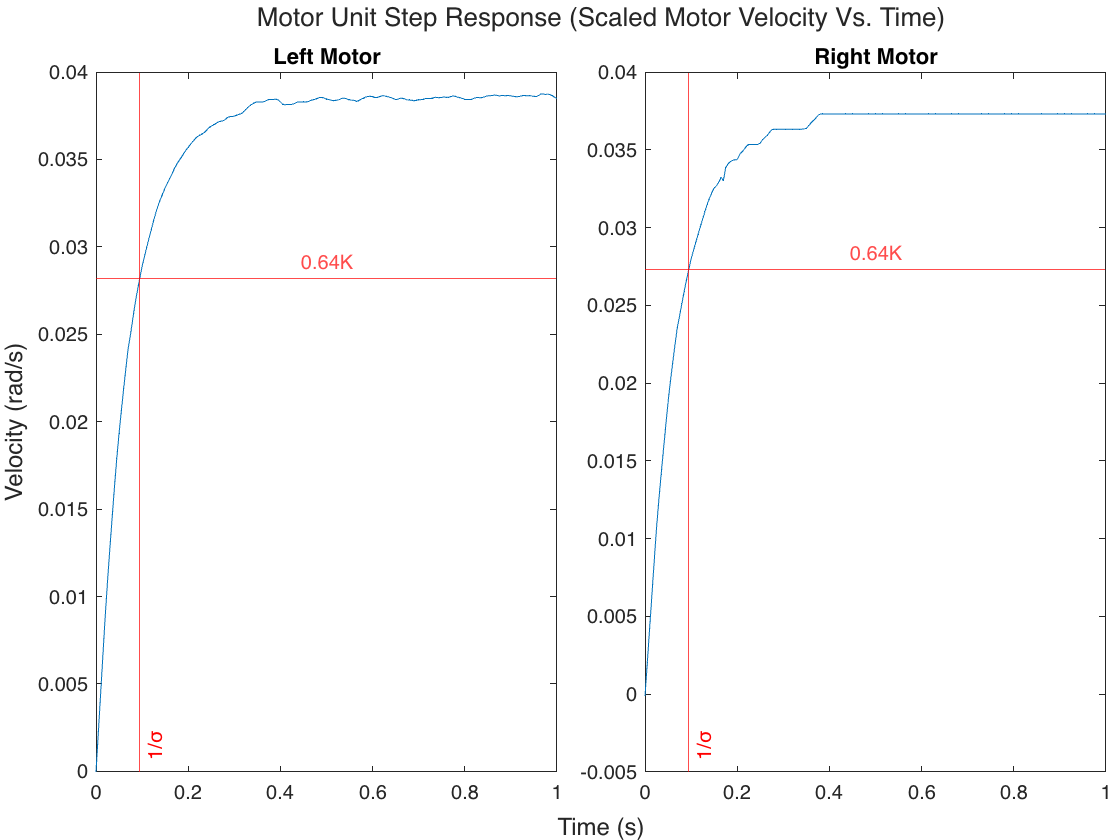

t2 = tiledlayout(1,2,"TileSpacing","compact",'Padding','tight');
xlabel(t2, 'Time (s)')
ylabel(t2, 'Velocity (rad/s)')
title(t2, 'Motor Unit Step Response (Scaled Motor Velocity Vs. Time)')

nexttile
plot(newT.time,newT.velL)
title('Left Motor')
yline(magAt64K_L,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_L,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

nexttile
plot(newT.time,newT.velR)
title('Right Motor')
yline(magAt64K_R,'Label','0.64K','Color','r',LabelHorizontalAlignment='center')
xline(TC_R,'Label','1/\sigma','Color','r','LabelVerticalAlignment','bottom')

Turn the generated transfer functions into coefficient arrays for use in Simulink.

posNum_R = posTF_R.Numerator;       % Find the numerator coefficients
posNum_R = posNum_R{1};             % Convert the numerator to a the right form
posDen_R = posTF_R.Denominator;     % Find the denominator coefficients
posDen_R = posDen_R{1};             % Convert the denominator to a the right form

velNum_R = velTF_R.Numerator;       % Find the numerator coefficients
velNum_R = velNum_R{1};             % Convert the numerator to a the right form
velDen_R = velTF_R.Denominator;     % Find the denominator coefficients
velDen_R = velDen_R{1};             % Convert the denominator to a the right form

posNum_L = posTF_L.Numerator;       % Find the numerator coefficients
posNum_L = posNum_L{1};             % Convert the numerator to a the right form
posDen_L = posTF_L.Denominator;     % Find the denominator coefficients
posDen_L = posDen_L{1};             % Convert the denominator to a the right form

velNum_L = velTF_L.Numerator;       % Find the numerator coefficients
velNum_L = velNum_L{1};             % Convert the numerator to a the right form
velDen_L = velTF_L.Denominator;     % Find the denominator coefficients
velDen_L = velDen_L{1};             % Convert the denominator to a the right form

#### Compare the Transfer Function with Motor Response

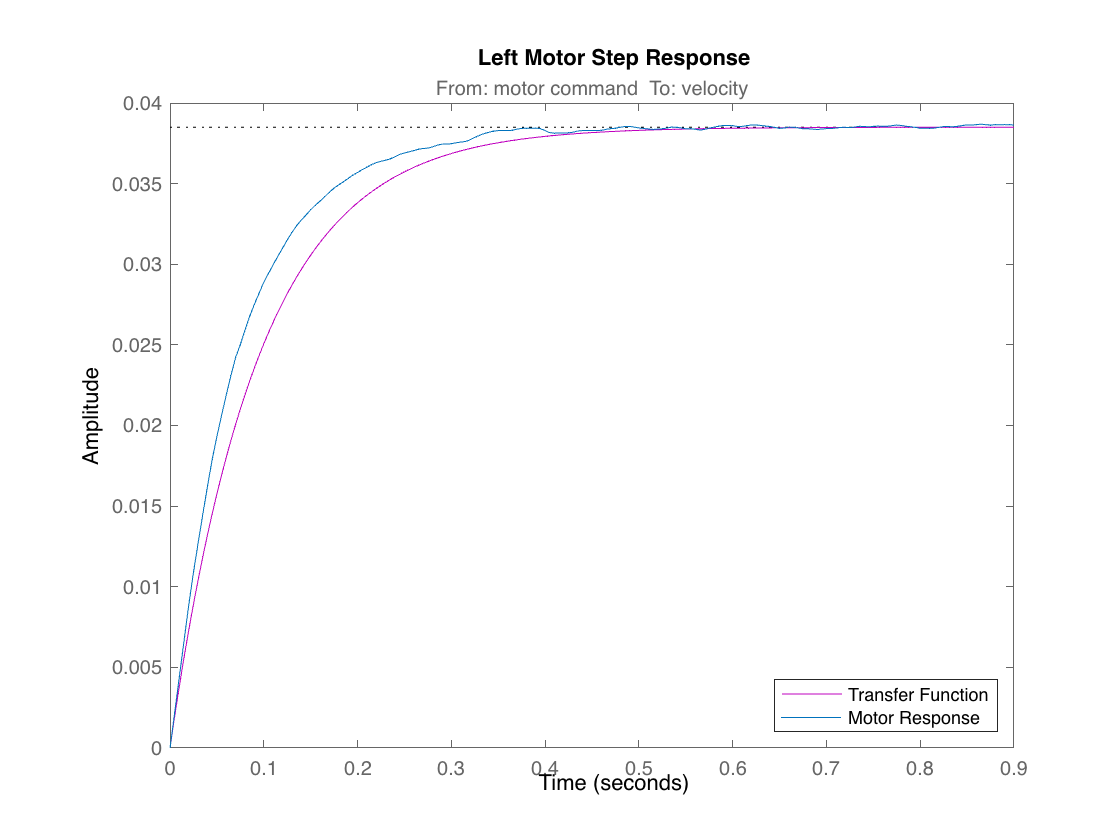

figure
stepplot(velTF_L,'m')
hold on
plot(newT.time,newT.velL)
title("Left Motor Step Response")
legend('Transfer Function','Motor Response','Location','southeast')
hold off

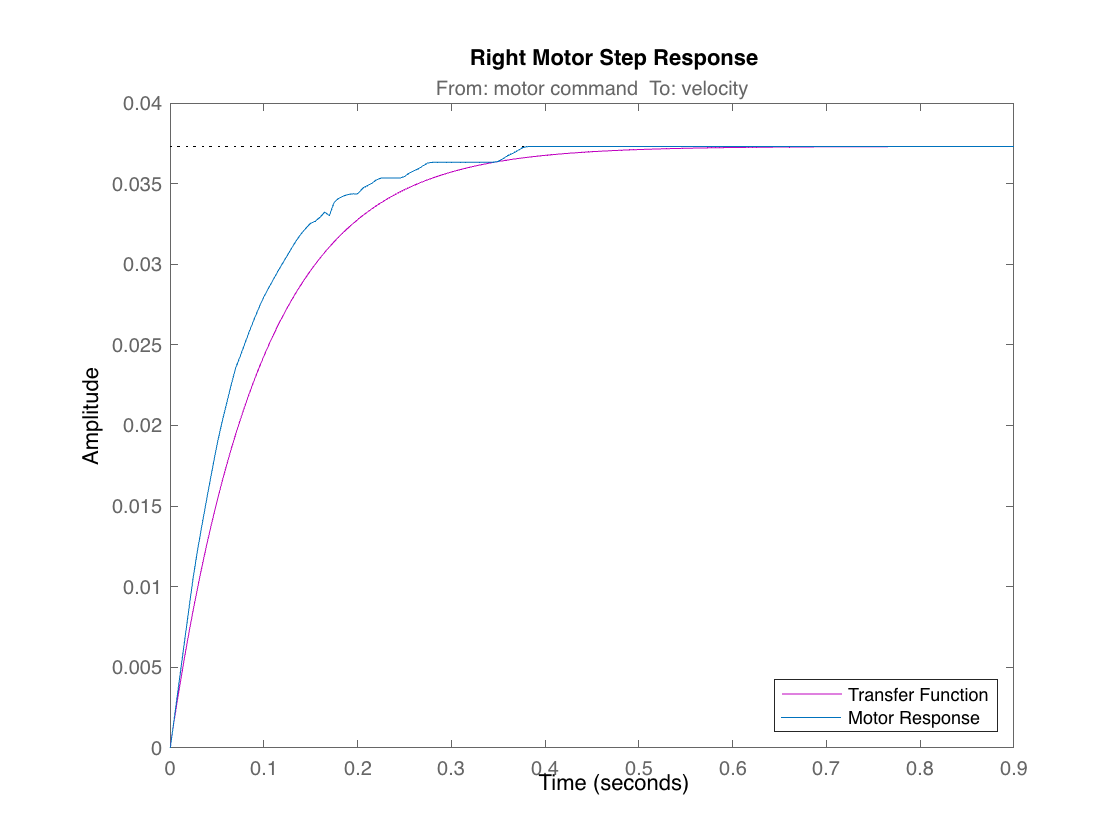


stepplot(velTF_R,'m')
hold on
plot(newT.time,newT.velR)
title("Right Motor Step Response")
legend('Transfer Function','Motor Response','Location','southeast')
hold off

Not sure if I want to display both graphs together

% figure
% p1 = subplot(2,1,1);
% stepplot(p1,velTF_L,'m');
% hold on
% plot(p1,newT.time,newT.velL);
% hold off
% title("Left Motor Step Response")
% 
% p2 = subplot(2,1,2);
% stepplot(p2, velTF_R,'m');
% hold on
% plot(p2, newT.time,newT.velR);
% hold off
% title("Right Motor Step Response")
% lgd = legend('Transfer Function','Motor Response','Location','east');

#### Design a PI Controller to Regulate Position

Design a PI controller that achieves closed loop step response specifications of a rise time of 1 second and an overshoot of less than or equal to 12%, with zero steady state error.

figure

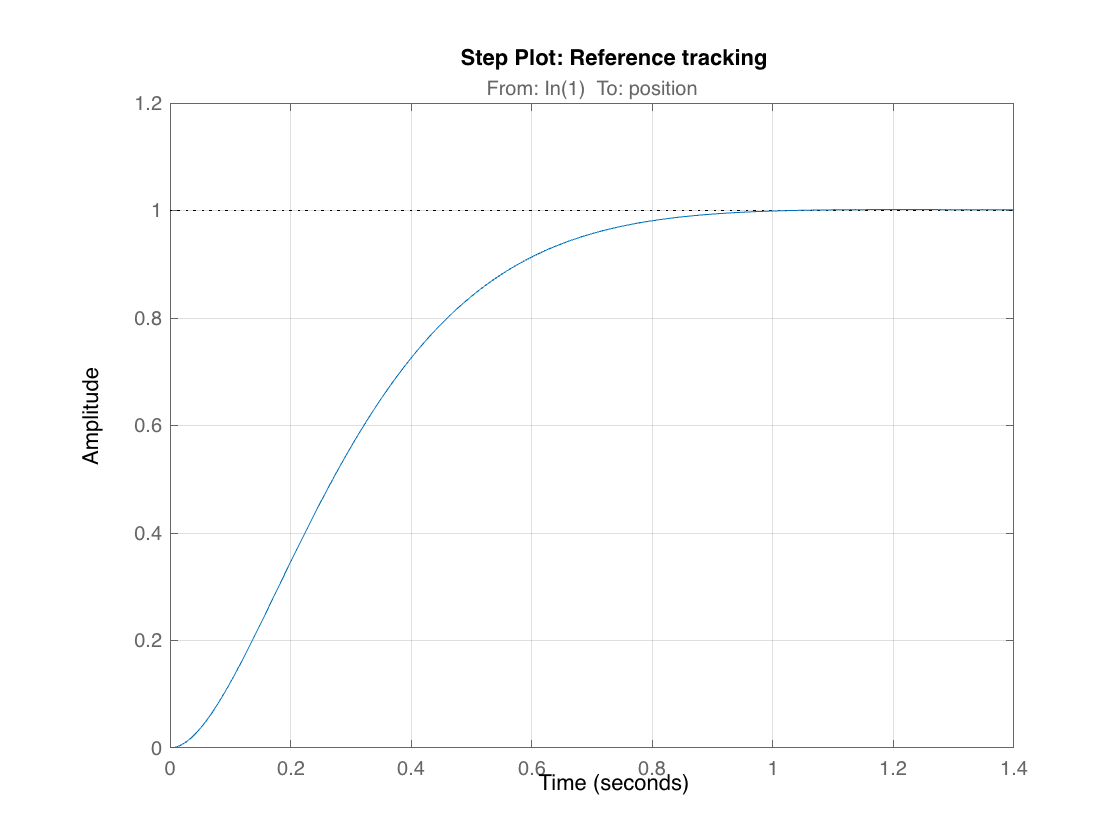

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.637509;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.729;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[C_L,pidInfo] = pidtune(posTF_L,'PD',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response = getPIDLoopResponse(C_L,posTF_L,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.4885
    TransientTime: 0.7944
     SettlingTime: 0.7944
      SettlingMin: 0.9000
      SettlingMax: 1.0017
        Overshoot: 0.1728
       Undershoot: 0
             Peak: 1.0017
         PeakTime: 1.2075




% Clear Temporary Variables
clear Response
KP_L = C_L.Kp, KD_L = C_L.Kd

KP_L = 85.0232

KD_L = 0

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/0.637509;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.729;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2);

% PID tuning algorithm for linear plant model
[C_R,pidInfo] = pidtune(posTF_R,'PD',wc2,opts2);

% Clear Temporary Variables
clear wc2 PM2 opts2

% Get desired loop response
Response2 = getPIDLoopResponse(C_R,posTF_R,'closed-loop');

% Plot the result
stepplot(Response2)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response2))

         RiseTime: 0.4885
    TransientTime: 0.7944
     SettlingTime: 0.7944
      SettlingMin: 0.9000
      SettlingMax: 1.0017
        Overshoot: 0.1728
       Undershoot: 0
             Peak: 1.0017
         PeakTime: 1.2075




% Clear Temporary Variables
clear Response2
KP_R = C_R.Kp, KI_R = C_R.Ki

KP_R = 87.7483

KI_R = 0

## Designing a controller for forward and rotational speed


$$\overline{V}_{a} = V_{a,1} + V_{a,2}$$



$$\Delta{V}_{a} = V_{a,1} - V_{a,2}$$


Va,1 and Va,2 are the voltage commands for the left and right motors

$\overline{V}_a$ is the magnitude of the combined voltage commands. Used for the forward speed $\dot{\rho}_d$ 

$\Delta V_a$ is the difference between the two voltage commands. Used for rotational speed $\dot{\phi}_d$

Forward velocity to voltage command:            $G_{\rho}(s) = \frac{\dot{\rho}(s)}{\overline{V}_a(s)}$

Rotational velocity to voltage command:        $G_{\phi}(s) = \frac{\dot{\phi}(s)}{\Delta V_a(s)}$